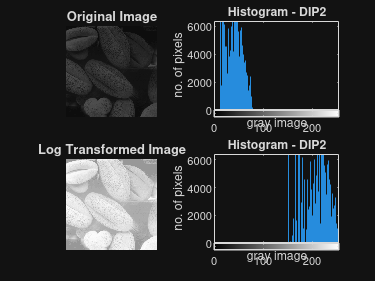

% log transformation
clc=--;
clear;
close all;


img = imread("Image-processing/DIP2.tif"); 

if size(img,3) == 3
    img = rgb2gray(img);
end

% Convert to double
img_double = double(img);

% Log Transformation
c = 255 / log(1 + max(img_double(:)));   % Scaling constant
log_image = c * log(1 + img_double);

% Convert back to uint8
log_image = uint8(log_image);

% Show Original Image
subplot(2,2,1);
imshow(img);
title('Original Image');

subplot(2,2,2);
imhist(img);
xlabel("gray image")
ylabel("no. of pixels");
title('Histogram - DIP2');


% Show Log Transformed Image
subplot(2,2,3);
imshow(log_image);
title('Log Transformed Image');

subplot(2,2,4);
imhist(log_image);
xlabel("gray image")
ylabel("no. of pixels");
title('Histogram - DIP2');